### Zadanie 1) Identyfikacja transmitancji obiektu na podstawie pomiarów

Na podstawie pomiarów odpowiedzi obiektu G1 na skok jednostkowy należy wykonać identyfikacje modelem G2 (Obiekt estymowany):

Warunek początkowy x0 = [1,0,0,0],  gdzie x0 = [x(1), x(2), x(3), x(4)].  

Wynik optymalizacji: G2=tf([0 1],[x(1) x(2) x(3) x(4)])

#### a)    Optymalizacja bez ograniczeń

Wykorzystując funkcje "fminsearch", należy wykonać identyfikacje modelu symulującego obiekt rzeczywisty (skrypt) modelem transmitancji G2 trzeciego rzędu.

x0 = [1,0,0,0]; %

options = optimset();
figure;
[x,fval,exitflag] = fminsearch(@ident,x0,options)

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 189.938018 



x =     0.0103   43.1371   -4.0209    2.2668


fval = 189.9380

exitflag = 0


G1=tf([0 1],[1 2 2.25 1.25]);
[G1p_Licz,G1p_Mian]=pade(0.5,3);
G1p=tf(G1p_Licz,G1p_Mian);
G1=G1*G1p

G1 =
 
                   -s^3 + 24 s^2 - 240 s + 960
  --------------------------------------------------------------
  s^6 + 26 s^5 + 290.2 s^4 + 1495 s^3 + 2490 s^2 + 2460 s + 1200
 
Continuous-time transfer function.




G2=tf([0 0.8],[x(1) x(2) x(3) x(4)])

G2 =
 
                    0.8
  ----------------------------------------
  0.0103 s^3 + 43.14 s^2 - 4.021 s + 2.267
 
Continuous-time transfer function.




isstable(G2)

ans = logical
   0


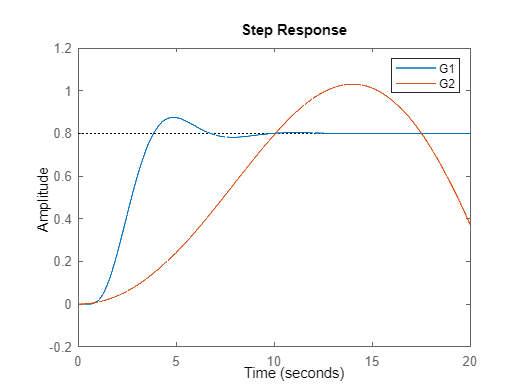

t=0:0.01:20;
figure;
step(G1,G2, t);
legend(["G1", "G2"]);

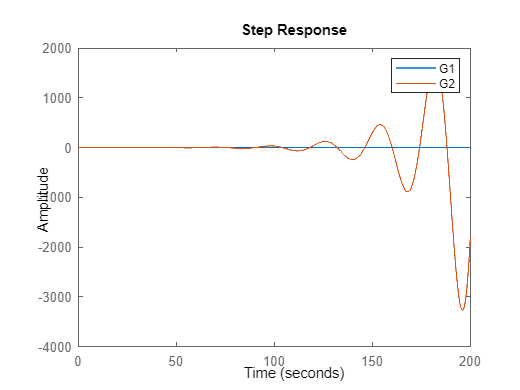


t=0:0.01:200;
figure;
step(G1,G2, t);
legend(["G1", "G2"]);


[z,p,k] =tf2zp(b,a)


z =

  0×1 empty double column vector



p =   -0.3265 + 0.9080i
  -0.3265 - 0.9080i
  -0.6221 + 0.0000i


k = 0.4654

x0 = [1,0,0,0]; %

options = optimset();
figure;
[x,fval,exitflag] = fminsearch(@ident_mod,x0,options)

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 38.475054 



x =     0.0000    5.1037    1.2410    1.0904


fval = 38.4751

exitflag = 0


G1=tf([0 1],[1 2 2.25 1.25]);
[G1p_Licz,G1p_Mian]=pade(0.5,3);
G1p=tf(G1p_Licz,G1p_Mian);
G1=G1*G1p

G1 =
 
                   -s^3 + 24 s^2 - 240 s + 960
  --------------------------------------------------------------
  s^6 + 26 s^5 + 290.2 s^4 + 1495 s^3 + 2490 s^2 + 2460 s + 1200
 
Continuous-time transfer function.




G2=tf([0 0.8],[x(1) x(2) x(3) x(4)])

G2 =
 
                     0.8
  ------------------------------------------
  2.032e-05 s^3 + 5.104 s^2 + 1.241 s + 1.09
 
Continuous-time transfer function.




isstable(G2)

ans = logical
   1


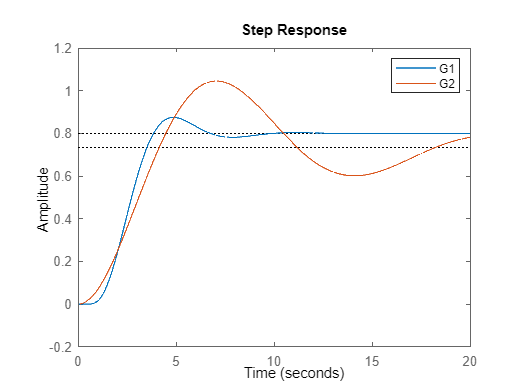

t=0:0.01:20;
figure;
step(G1,G2, t);
legend(["G1", "G2"]);

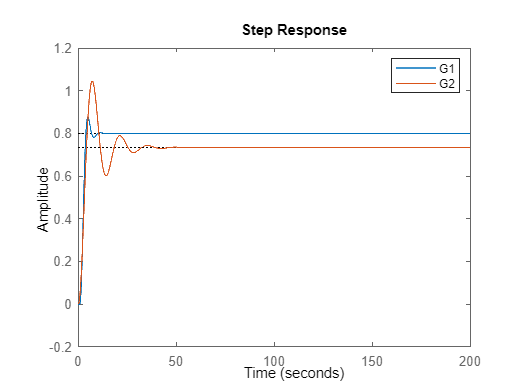


t=0:0.01:200;
figure;
step(G1,G2, t);
legend(["G1", "G2"]);


[z,p,k] =tf2zp(b,a)


z =

  0×1 empty double column vector



p =   -0.3265 + 0.9080i
  -0.3265 - 0.9080i
  -0.6221 + 0.0000i


k = 0.4654

#### b)    Optymalizacja z ograniczeniami

Wykorzystując funkcje "fmincon", należy wykonać identyfikacje modelu symulującego obiekt rzeczywisty (skrypt) modelem transmitancji trzeciego rzędu, przy ograniczeniach równościowych i  nierównościowych spełniających kryterium Hurwitza.

Wskazówka:

Rozważyć rożne warunki początkowe np: x0 = [1,10,10,1];

Przykładowe rozwiązanie:

x0 = [1,10,10,1];

opts = optimoptions('fmincon','Display','iter','Algorithm','sqp');
figure;
x = fmincon(@ident,x0,[],[],[],[],[],[],@Hurwitz,opts)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           5    1.977745e+02     0.000e+00     1.000e+00     0.000e+00     1.514e+02  
    1          25    1.786872e+02     0.000e+00     4.748e-03     7.290e-01     2.049e+02  
    2          31    7.126995e+01     0.000e+00     7.000e-01     7.506e+00     2.237e+02  
    3          38    6.601696e+01     0.000e+00     4.900e-01     2.857e+00     8.015e+01  
    4          43    1.406867e+01     0.000e+00     1.000e+00     5.949e+00     7.480e+01  
    5          49    5.549551e+00     0.000e+00     7.000e-01     2.136e+00     4.418e+01  
    6          55    4.565343e+00     0.000e+00     7.000e-01     1.024e+00     7.529e+01  
    7          60    3.655575e+00     0.000e+00     1.000e+00     2.341e+00     5.023e+00  
    8          65    1.316202e+00     0.000e+00     1.000e+00     1.238e+00     1.

x =     1.7190    2.1919    2.2990    0.9957



G1=tf([0 1],[1 2 2.25 1.25]);
[G1p_Licz,G1p_Mian]=pade(0.5,3);
G1p=tf(G1p_Licz,G1p_Mian);
G1=G1*G1p

G1 =
 
                   -s^3 + 24 s^2 - 240 s + 960
  --------------------------------------------------------------
  s^6 + 26 s^5 + 290.2 s^4 + 1495 s^3 + 2490 s^2 + 2460 s + 1200
 
Continuous-time transfer function.



G2=tf([0 0.8],[x(1) x(2) x(3) x(4)])

G2 =
 
                    0.8
  ----------------------------------------
  1.719 s^3 + 2.192 s^2 + 2.299 s + 0.9957
 
Continuous-time transfer function.



t=0:0.01:20;

figure;
isstable(G2)

ans = logical
   1


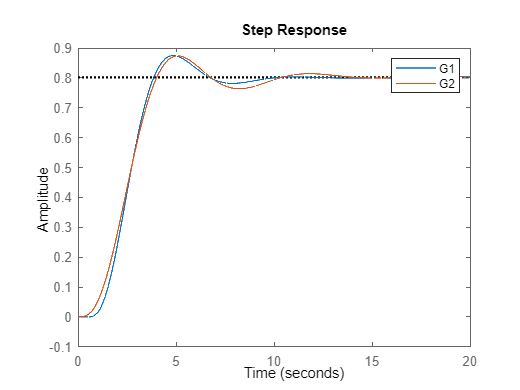

step(G1, G2, t);
legend(["G1", "G2"]);


[z,p,k] =tf2zp(b,a)


z =

  0×1 empty double column vector



p =   -0.3265 + 0.9080i
  -0.3265 - 0.9080i
  -0.6221 + 0.0000i


k = 0.4654

x0 = [1, 0, 0, 0];

opts = optimoptions('fmincon','Display','iter','Algorithm','sqp');
figure;
x = fmincon(@ident,x0,[],[],[],[],[],[], @Hurwitz,opts)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           5    3.247956e+08     1.000e+00     1.000e+00     0.000e+00     3.038e+10  
    1          63    1.102854e+03     0.000e+00     6.169e-09     1.984e+02     6.305e-02  
    2          68    1.102853e+03     0.000e+00     1.000e+00     2.599e-02     6.297e-02  
    3          73    1.102850e+03     0.000e+00     1.000e+00     1.300e-01     6.254e-02  
    4          79    1.102845e+03     0.000e+00     7.000e-01     4.554e-01     7.308e-02  
    5          84    1.102841e+03     0.000e+00     1.000e+00     5.675e-02     6.088e-02  
    6          89    1.102815e+03     0.000e+00     1.000e+00     6.946e-01     6.045e-02  
    7          98    1.102746e+03     0.000e+00     2.401e-01     2.274e+00     4.623e-01  
    8         111    1.102734e+03     0.000e+00     5.765e-02     3.455e-01     5.

x =     5.4624   15.5381   65.5880  186.5682



G1=tf([0 1],[1 2 2.25 1.25]);
[G1p_Licz,G1p_Mian]=pade(0.5,3);
G1p=tf(G1p_Licz,G1p_Mian);
G1=G1*G1p

G1 =
 
                   -s^3 + 24 s^2 - 240 s + 960
  --------------------------------------------------------------
  s^6 + 26 s^5 + 290.2 s^4 + 1495 s^3 + 2490 s^2 + 2460 s + 1200
 
Continuous-time transfer function.



G2=tf([0 0.8],[x(1) x(2) x(3) x(4)])

G2 =
 
                    0.8
  ---------------------------------------
  5.462 s^3 + 15.54 s^2 + 65.59 s + 186.6
 
Continuous-time transfer function.



t=0:0.01:20;

figure;
isstable(G2)

ans = logical
   1


Hurwitz(x)

ans = -1

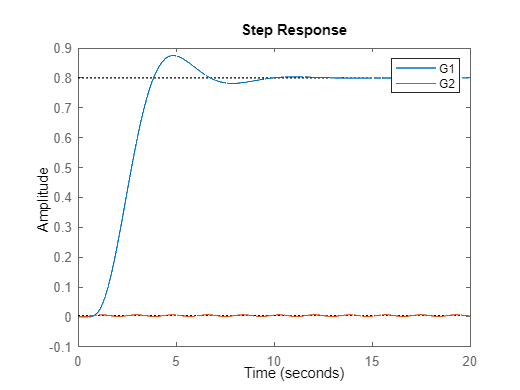

step(G1, G2, t);
legend(["G1", "G2"]);


[z,p,k] =tf2zp(b,a)


z =

  0×1 empty double column vector



p =   -0.3265 + 0.9080i
  -0.3265 - 0.9080i
  -0.6221 + 0.0000i


k = 0.4654

x0 = [20,1,10,1];

opts = optimoptions('fmincon','Display','iter','Algorithm','sqp');
figure;
x = fmincon(@ident,x0,[],[],[],[],[],[],@Hurwitz,opts)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           5    1.844727e+02     1.000e+00     1.000e+00     0.000e+00     2.081e+02  
    1          26    1.506530e+02     0.000e+00     3.323e-03     6.969e-01     2.385e+02  
    2          31    1.160918e+02     0.000e+00     1.000e+00     5.927e+00     1.727e+02  
    3          36    9.320280e+01     0.000e+00     1.000e+00     4.273e+00     3.416e+01  
    4          46    7.548940e+01     1.000e+00     1.681e-01     3.674e+00     3.322e+01  
    5          52    4.902167e+01     0.000e+00     7.000e-01     1.163e+01     4.877e+02  
    6          66    3.960769e+01     0.000e+00     4.035e-02     9.426e-01     4.406e+02  
Objective function returned NaN; trying a new point...
    7          96    3.958526e+01     0.000e+00     1.341e-04     3.747e-03     4.405e+02  
Objective function returned

x =     1.7190    2.1919    2.2990    0.9957



G1=tf([0 1],[1 2 2.25 1.25]);
[G1p_Licz,G1p_Mian]=pade(0.5,3);
G1p=tf(G1p_Licz,G1p_Mian);
G1=G1*G1p

G1 =
 
                   -s^3 + 24 s^2 - 240 s + 960
  --------------------------------------------------------------
  s^6 + 26 s^5 + 290.2 s^4 + 1495 s^3 + 2490 s^2 + 2460 s + 1200
 
Continuous-time transfer function.



G2=tf([0 0.8],[x(1) x(2) x(3) x(4)])

G2 =
 
                    0.8
  ----------------------------------------
  1.719 s^3 + 2.192 s^2 + 2.299 s + 0.9957
 
Continuous-time transfer function.



t=0:0.01:20;

figure;
isstable(G2)

ans = logical
   1


step(G1, G2, t);
legend(["G1", "G2"]);


[z,p,k] =tf2zp(b,a)


z =

  0×1 empty double column vector



p =   -0.3265 + 0.9080i
  -0.3265 - 0.9080i
  -0.6221 + 0.0000i


k = 0.4654

function [c,ceq] = Hurwitz(x)
c = 1;
ceq = [];

if all(x > 0)
    %do nothing
%elseif all(x < 0)
%    x = -x;
else
    %does not satisify 1st condition
    c = 1; 
    return;
end %if

H=[x(2) x(4)  0;
   x(1) x(3) 0;
   0 x(2) x(4)];

H1=H(1,1);
H2=H(1:2,1:2);
Det_H1=det(H1);
Det_H2=det(H2);
Det_H=det(H);

if Det_H1 > 0 && Det_H2 > 0 && Det_H > 0
    c = -1;
else
    c = 1;
end %if

end %Hurwitz

function blad = ident(x)

t=0:0.01:20;
G1=tf([0 1],[1 2 2.25 1.25]);
[G1p_Licz,G1p_Mian]=pade(0.5,3);
G1p=tf(G1p_Licz,G1p_Mian);
G1=G1*G1p;


G2=tf([0 0.8],[x(1) x(2) x(3) x(4)]);
[y1] = step(G1,t); % wzor
[y2] = step(G2,t); % dopasowanie

e = y1-y2;
blad= sum(e.^2);
end

function blad = ident_mod(x)

t=0:0.01:20;
G1=tf([0 1],[1 2 2.25 1.25]);
[G1p_Licz,G1p_Mian]=pade(0.5,3);
G1p=tf(G1p_Licz,G1p_Mian);
G1=G1*G1p;


G2=tf([0 0.8],[x(1) x(2) x(3) x(4)]);
[y1] = step(G1,t); % wzor
[y2] = step(G2,t); % dopasowanie

e = y1-y2;
blad= sum(e.^2)+10*max(e.^2);
end